clc;
clear; 
cvx_clear;

%mu - gravitational parameter (m3/s2)
mu = 3.986e14

mu = 3.9860e+14


%radius of Earth (m)
r_e = 6.371e6

r_e = 6371000


%altitude of the target orbit (m)
altitude = 422137

altitude = 422137


%a - radius of the target body's circular orbit (m)
a = r_e + altitude

a = 6793137


%constant mean motion of target n = sqrt(mu/a^3)
%units: rad/s
n = sqrt(mu/a^3)

n = 0.0011


%this was working before..
%n = 0.0010831 

%number of states
nx = 6

nx = 6


%number of control inputs
nu = 3

nu = 3


%number of knot points
N = 2500

N = 2500


%timestep (seconds)
dt = 1

dt = 1


%time history
thist = linspace(1, N*dt, N)

thist =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



%Target Spacecraft State
x0_target = zeros(1, nx)'

x0_target =      0
     0
     0
     0
     0
     0



%Chaser Spacecraft Initial State
%position - m
%velocity - m/s
x0_chaser = [15.0, 20.0, 15.0, 10.0, 10.0, 0.0]'

x0_chaser =     15
    20
    15
    10
    10
     0



%Clohessy Wiltshire Equations in statespace form

A = zeros(nx, nx)

A =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(1:3, 4:6) = eye(3)

A =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(4, 1) = 3*n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


A(6, 3) = -n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(4, 5) = 2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0023         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(5, 4) = -2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0023         0
         0         0         0   -0.0023         0         0
         0         0   -0.0000         0         0         0



%mass of the satellite (kg)
m = 1

m = 1


B = 1/m*[zeros(3,3); eye(3)]

B =      0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



%Spacecraft Linear Dynamics
%CW equations
function xdot = spacecraft_dynamics(x, u)

    xdot = A*x + B*u

end

%Discretize the dynamics model 
%with matrix exponential

H = expm(dt*[A B; zeros(nu, nx+nu)])

H =     1.0000         0         0    1.0000    0.0011         0    0.5000    0.0004         0
   -0.0000    1.0000         0   -0.0011    1.0000         0   -0.0004    0.5000         0
         0         0    1.0000         0         0    1.0000         0         0    0.5000
    0.0000         0         0    1.0000    0.0023         0    1.0000    0.0011         0
   -0.0000         0         0   -0.0023    1.0000         0   -0.0011    1.0000         0
         0         0   -0.0000         0         0    1.0000         0         0    1.0000
         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0    1.0000



%Discrete Dynamics Matrices
Ad  = H(1:nx, 1:nx)

Ad =     1.0000         0         0    1.0000    0.0011         0
   -0.0000    1.0000         0   -0.0011    1.0000         0
         0         0    1.0000         0         0    1.0000
    0.0000         0         0    1.0000    0.0023         0
   -0.0000         0         0   -0.0023    1.0000         0
         0         0   -0.0000         0         0    1.0000


Bd = H(1:nx, (nx+1):end)

Bd =     0.5000    0.0004         0
   -0.0004    0.5000         0
         0         0    0.5000
    1.0000    0.0011         0
   -0.0011    1.0000         0
         0         0    1.0000



%initial position in target center
%coordinate frame
x_initial = x0_chaser

x_initial =     15
    20
    15
    10
    10
     0



%Goal is the target position
x_goal = x0_target

x_goal =      0
     0
     0
     0
     0
     0



cvx_begin

   %solver 
   cvx_solver sedumi

   %precision for solver tolerance
   cvx_precision('low')

   %maximum iterations
   %cvx_solver_settings('maxit', 1000);

    %state trajectory 
   variable X(nx, N)

   %Controls
   variable U(nu, N-1)

   %minimize the L1 norm to get bang bang controls
   minimize(norm(U(:),1))

   subject to

       %initial state
       X(:,1) == x_initial
    
       %Goal constraint
       X(:, N) == x_goal
    
       %Thrust Limit Constraint
       for k=1:(N-1)
           
           norm(U(:,k)) <= 0.06

       end
    
       %Dynamics Constraints
    
       for k=1:N-1
           X(:,k+1) == Ad*X(:,k) + Bd*U(:,k)
       end

cvx_end

 
Calling SeDuMi 1.02,: 37477 variables, 19990 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 19990, order n = 22494, dim = 37479, blocks = 2501
nnz(A) = 122421 + 0, nnz(ADA) = 187382, nnz(L) = 138654
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.55E+05 0.000
  1 :  -9.46E+01 6.75E+04 0.000 0.4358 0.9000 0.9000   3.00  1  1  2.8E+00
  2 :  -1.33E+02 2.67E+04 0.000 0.3961 0.9000 0.9000   1.56  1  1  1.3E+00
  3 :  -1.35E+02 1.34E+04 0.000 0.5018 0.9000 0.9000   1.20  1  1  8.7E-01
  4 :  -1.32E+02 7.32E+03 0.000 0.5454 0.9000 0.9000   1.10  1  1  7.0E-01
  5 :  -1.25E+02 4.56E+03 0.000 0.6223 0.9000 0.9000   1.07  1  1  6.2E-01
  6 :  -1.18E+02 2.90E+03 0.000 0.6374 0.9000 0.9000   1.06  1  1  5.8E-01
  7 :  -1.08E+02 2.21E+03 0

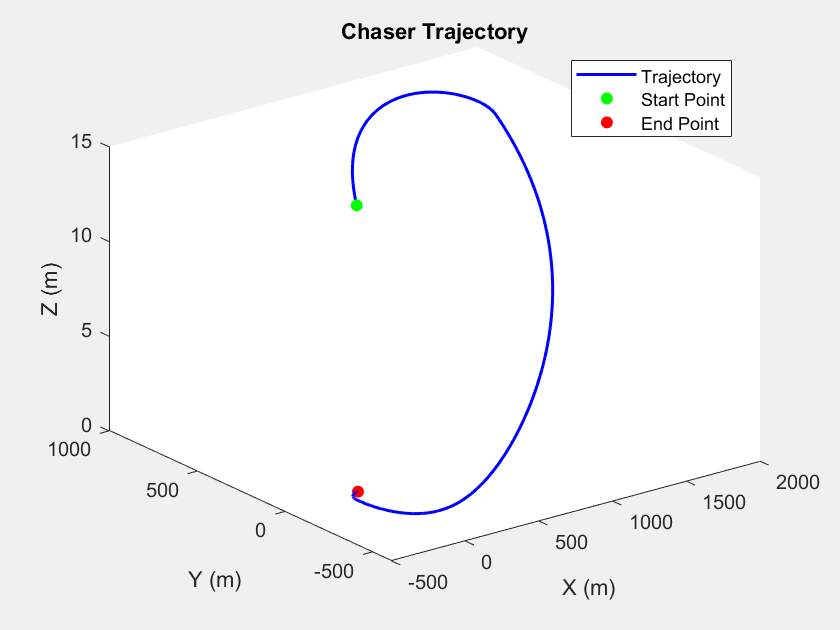


figure('Name', 'My Plot', 'NumberTitle', 'off', 'Visible', 'on');

% Plot the data
plot3(X(1,:), X(2,:), X(3,:), '-b', 'LineWidth', 1.5);
hold on
scatter3(X(1,1), X(2,1), X(3,1), "green", "filled")
scatter3(X(1,N), X(2,N), X(3,N), "red", "filled")
hold off

% Add title and labels
title('Chaser Trajectory');
xlabel('X (m)');
ylabel('Y (m)');
zlabel("Z (m)")

legend('Trajectory', 'Start Point', 'End Point', 'Location', 'best');

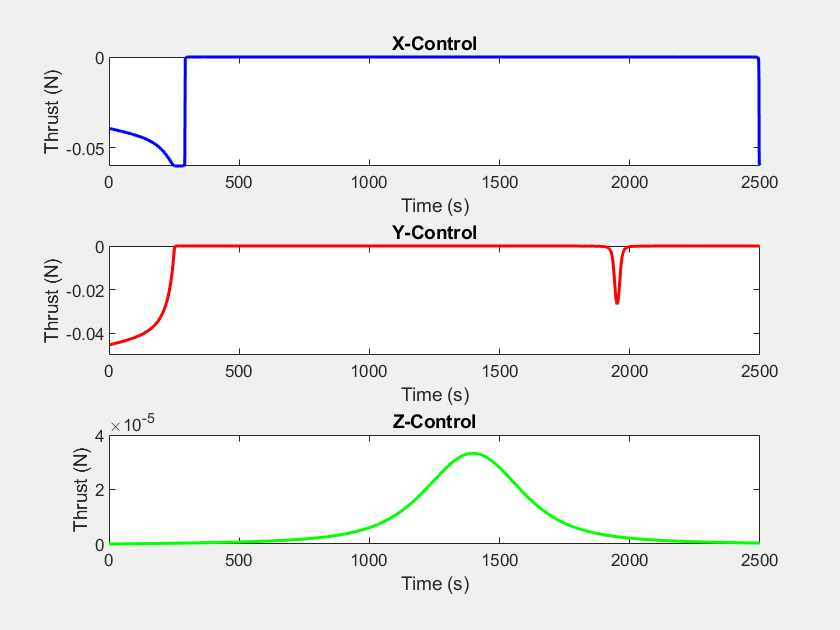


% Create a new figure window
figure('Name', 'Multiple Subplots', 'NumberTitle', 'off', 'Visible', 'on', 'WindowStyle', 'normal');

% First subplot
subplot(3, 1, 1); 
plot(thist(1, 1:N-1), U(1,:), '-b', 'LineWidth', 1.5); 
title('X-Control');
xlabel('Time (s)');
ylabel('Thrust (N)');

% Second subplot
subplot(3, 1, 2);
plot(thist(1, 1:N-1), U(2,:), '-r', 'LineWidth', 1.5); 
title('Y-Control');
xlabel('Time (s)');
ylabel('Thrust (N)');

% Third subplot
subplot(3, 1, 3); 
plot(thist(1, 1:N-1), U(3,:), '-g', 'LineWidth', 1.5); 
title('Z-Control');
xlabel('Time (s)');
ylabel('Thrust (N)');